%Example 1
ds = datastore('1987.csv');

ds.TreatAsMissing = 'NA';
ds.MissingValue = 0;

ds.SelectedVariableNames = {'UniqueCarrier','Month','DayofMonth','Distance','ArrDelay'};

ds.ReadSize = 40000;
preview(ds)

ans = 8×5 table
    UniqueCarrier    Month    DayofMonth    Distance    ArrDelay
    _____________    _____    __________    ________    ________

       {'PS'}         10          14          447          23   
       {'PS'}         10          15          447          14   
       {'PS'}         10          17          447          29   
       {'PS'}         10          18          447          -2   
       {'PS'}         10          19          447          33   
       {'PS'}         10          21          447          -1   
       {'PS'}         10          22          447           3   
       {'PS'}         10          23          447          13   


Result = [];

while hasdata(ds)
    temp = read(ds);
    over1500 = temp.Distance>=1500;
    temp = temp(over1500,:);
    Result = [Result;temp];
end

%Example 2
ds = datastore('1987.csv');

ds.TreatAsMissing = 'NA';
%ds.MissingValue = 0;

ds.SelectedVariableNames = {'ArrDelay'};

ds.ReadSize = 40000;
preview(ds)

ans = 8×1 table
    ArrDelay
    ________

       23   
       14   
       29   
       -2   
       33   
       -1   
        3   
       13   


%Calculate Arrdelay mean
Result = [];
%while hasdata(ds)
%    temp = read(ds);
%    sums = mean(temp.ArrDelay) + sums;
%    count = count + 1;
%end
%means = sums/count;

while hasdata(ds)
    temp = read(ds);
    MissingIdx = ismissing(temp);
    temp = temp(~MissingIdx,:);
    tempResult = [sum(temp.ArrDelay),height(temp)];
    Result = [Result;tempResult];
end

ArrDelay_Mean = sum(Result(:,1))/sum(Result(:,2))

ArrDelay_Mean = 9.4467

%Example 3
ds = datastore('1987.csv');
ds.TreatAsMissing = 'NA';
ds.SelectedVariableNames = {'ArrDelay'};
mytall = tall(ds);
dataLength = height(mytall);
ArrDelay_Mean = gather(nanmean(mytall.ArrDelay));

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 0.99 sec
Evaluation completed in 1.2 sec


%Machine Learning
load ionosphere
ionosphere = array2table(X);
ionosphere.Group = Y;
idx = fscchi2(ionosphere,'Group');
ionosphere_selected = ionosphere(:,idx(1:10))

ionosphere_selected = 351×10 table
       X5          X7          X3          X8          X6          X4         X28         X13        X21         X15   
    ________    ________    ________    ________    ________    ________    ________    _______    ________    ________

     0.85243     0.83398     0.99539    -0.37708     0.02306    -0.05889    -0.46168    0.59755     0.56971     0.60536
     0.93035    -0.10868           1    -0.93597    -0.36156    -0.18829    -0.18401    0.34432    -0.13151    -0.51685
           1           1           1    -0.12062     0.00485    -0.03365    -0.22145    0.85443     0.70887     0.54591
           1     0.71216

%Credit card Fraud Detection
creditData = datastore('creditcard.csv');
creditDataTall = tall(creditData);
creditDataTall.Class = categorical(creditDataTall.Class,{'0','1'},{'Normal','Fraud'});
histogram(creditDataTall.Class);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 1.2 sec
- Pass 2 of 2: Completed in 1.1 sec
Evaluation completed in 2.9 sec


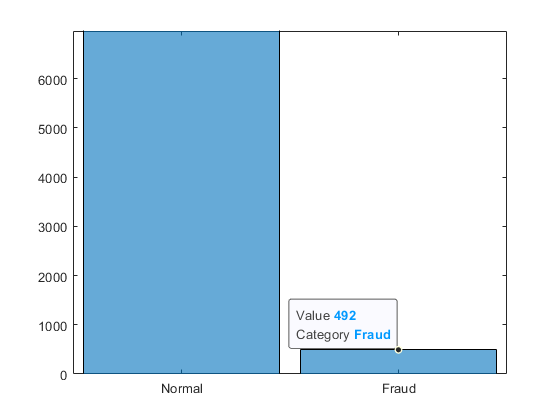


xlim({'Normal','Fraud'})
ylim([0 6965])
ax = gca;
chart = ax.Children(1);
datatip(chart,'Fraud',492);

gather(countcats(creditDataTall.Class))

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 1.4 sec
Evaluation completed in 1.7 sec


ans =       284315
         492


FraudIdx = creditDataTall.Class == "Fraud";
FraudData = creditDataTall(FraudIdx,:);
%%
NormalData = datasample(creditDataTall(~FraudIdx,:),1000,'Replace',false);
combineData = [NormalData;FraudData];
%%
cvp = cvpartition(table2array(combineData),"HoldOut",0.3);

Error using tall/table2array (line 10)
Invalid combination of data types for concatenation: categorical double.

trainingData = combineData(cvp.training,:);
testingData = combineData(cvp.test,:);
%%
model = fitcecoc(trainingData(:,1:end-2),trainingData.Class)